Autorzy: Krzysztof S, Hubert K

Operacje na sygnałach - dodawanie graficzne

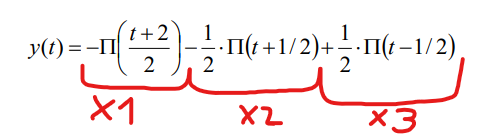

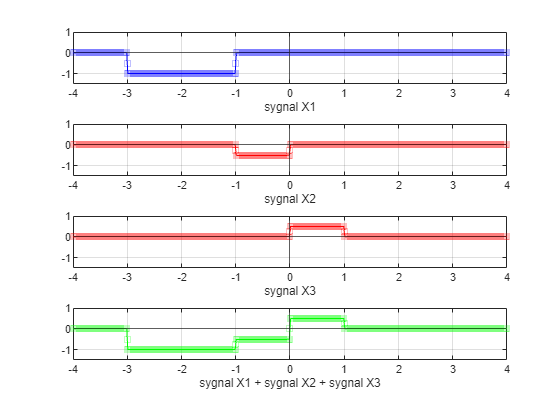

clc; clear; close all;
addpath("funkcje_pomocnicze");

% dziedzina wykresu
okres_probkowania = 1 /100; 



% Kontrolki od sygnału X1

amplituda_x1 =-1; %default = -1
opoznienie_x1 =-2; %default = -2
wydluzenie_x1 =0.5; %default = 0.5 

% Kontrolki od sygnału X2

amplituda_x2 = -0.5; %default = -0.5
opoznienie_x2 = -0.5; %default = -0.5
wydluzenie_x2 = 1; %default = 1

% Kontrolki od sygnału X3

amplituda_x3 =0.5; %default = 0.5
opoznienie_x3 =0.5; %default = 0.5
wydluzenie_x3 =1; %default = 1 



% poprawki żeby sygnał zachowywał się jak w równaniu przy podanych
% w przykładzie parametrach
wydluzenie_x1 = 1 / wydluzenie_x1;
wydluzenie_x2 = 1 / wydluzenie_x2;
wydluzenie_x3 = 1 / wydluzenie_x3;

%wykres view setup (granice okienka)
l_krawedz = -4; 
p_krawedz = 4;
g_krawedz = max([amplituda_x1, amplituda_x2, amplituda_x3]) + 0.5;
d_krawedz = min([g_krawedz * -1, amplituda_x1 - 0.5, amplituda_x2 - 0.5, amplituda_x3 - 0.5]);

t = l_krawedz : okres_probkowania : p_krawedz; %zeby program wiedzial zakres dziedziny
wymiary_wykresu = [l_krawedz, p_krawedz, d_krawedz, g_krawedz];
x1 = xpi(t, amplituda_x1, opoznienie_x1, wydluzenie_x1);
x2 = xpi(t, amplituda_x2, opoznienie_x2, wydluzenie_x2);
x3 = xpi(t, amplituda_x3, opoznienie_x3, wydluzenie_x3);
x4 = x1+x2+x3;

wykresx1 = {'sygnal X1', wymiary_wykresu, t, x1, 'b-square'};
wykresx2 = {'sygnal X2', wymiary_wykresu, t, x2, 'r-square'};
wykresx3 = {'sygnal X3', wymiary_wykresu, t, x3, 'r-square'};
wykresx4 = {'sygnal X1 + sygnal X2 + sygnal X3', wymiary_wykresu, t, x4, 'g-square'};

rysuj_subplot(wykresx1, wykresx2, wykresx3, wykresx4);